# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 100; % # sample points
A = 21; % Magnitude/Amplitude of droplet

xMax = 10; 
x0 = 1.2; % Shift
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
var = [A;N;k;y0]; 

% Set time span
tfinal = 10^5; % final time >> 1
tSpan = [1e-6 tfinal]; 

% Fixxed Disjoinning pressure
c0(1) = 0.0002;  
c0(2) = 0.0046;

% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2); % D2

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;
% Target shape is a parabola, not achievable

## **2) **

**Initial droplet centered around **`x0`

h0 = hFinal(x0,X,var,c0,D1,D2,tSpan);
H0 = deval(h0,tfinal); 

## **3)**

**Solution**

% Vertical/Function tolerance: 1e-1
% Horizontal tolerance: 1e-1
options = optimset('TolFun',1e-1,'TolX',1e-1,'MaxFunEvals',60,'MaxIter',50);

% % % Generate an object/function to be optimise
% % myObjective_Possition = @(x) costEvaluation(x,X,var,c0,D1,D2,tSpan,tfinal,h_target);
% % % in this case we have a cost function
% % 
% % figure;
% % plot(X,h_target,'k:','linewidth',2)
% % hold on
% % plot(X,H0,'*r')
% % ylim([0 5]);
% % % Solution of best center point: x_sol
% % x_Sol = fminsearch(myObjective_Possition,x0,options);
% % % resulting portfolio
% % h_Sol = hFinal(x_Sol,X,var,c0,D1,D2,tSpan);
% % % resulting final profile (at t = tfinal)
% % H_Sol = deval(h_Sol,tfinal);
% % 
% % plot(X,H_Sol,'*g')
% % legend('Exp Data','Initial Param','Best Param');

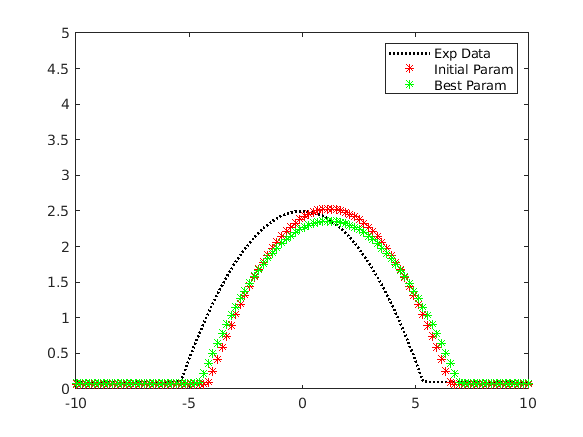

% Generate an object/function to be optimise
myObjective_Possition = @(c) costEvaluation(x0,X,var,c,D1,D2,tSpan,tfinal,h_target);
% in this case we have a cost function

figure;
plot(X,h_target,'k:','linewidth',2)
hold on
plot(X,H0,'*r')
ylim([0 5]);
% Solution of best center point: x_sol
c_Sol = fminsearch(myObjective_Possition,c0,options);
% resulting portfolio
h_Sol = hFinal(x0,X,var,c_Sol,D1,D2,tSpan);
% resulting final profile (at t = tfinal)
H_Sol = deval(h_Sol,tfinal);

plot(X,H_Sol,'*g')
legend('Exp Data','Initial Param','Best Param');